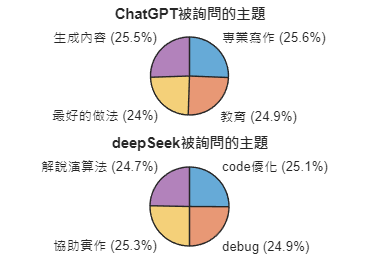

file = readtable("deepseek_vs_chatgpt.csv") ;
gptfile=file(strcmp(file.AI_Platform, 'ChatGPT'), 'Topic_Category');
deepseekfile=file(strcmp(file.AI_Platform, 'DeepSeek'), 'Topic_Category');

[gptTimes,gptType]=groupcounts(gptfile.Topic_Category);%出現次數 問題類型
[dsTimes,dsType]=groupcounts(deepseekfile.Topic_Category);

subplot(2,1,1);
piechart(gptTimes,gptType);
title('ChatGPT被詢問的主題');

subplot(2,1,2);
piechart(dsTimes,dsType);
title('deepSeek被詢問的主題');

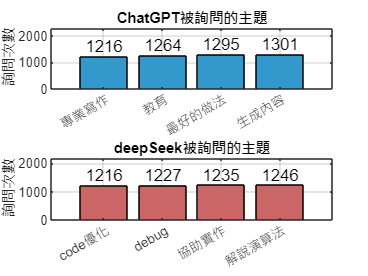

subplot(2,1,1);
gptBar=bar(gptType,sort(gptTimes));
gptBar.Labels=gptBar.YData;%為長條圖加上實際數字
ylabel('詢問次數');
title('ChatGPT被詢問的主題');
grid on;%網格線

subplot(2,1,2);
dsBar=bar(dsType,sort(dsTimes));
dsBar.Labels=dsBar.YData;
ylabel('詢問次數');
title('deepSeek被詢問的主題');
grid on;

gptBar.FaceColor = [0.2 0.6 0.8];  % 淡藍
dsBar.FaceColor = [0.8 0.4 0.4];   % 淡紅